## **Section 1 **

### **Part A)**

cd /home/uki/Documents/MATLAB/COVID-19-Wearables/

files = dir('*_hr.csv');
fileNames = {files.name};

for k = 1:numel(fileNames)
    hr{k} = readtable(fileNames{k});    
end

files = dir('*_steps.csv');
fileNames = {files.name};

for k = 1:numel(fileNames)
    steps{k} = readtable(fileNames{k});    
end

files = dir('*_sleep.csv');
fileNames = {files.name};

for k = 1:numel(fileNames)
    sleep{k} = readtable(fileNames{k});    
end

for i = 1:size(hr,2)
    meanhr(i) = mean(hr{1,i}.heartrate);
    sdhr(i) = std(hr{1,i}.heartrate);
end

for i = 1:size(sleep,2)
    sdsleep(i) = std(sleep{1,i}.stage_duration(sleep{1,i}.stage ~= "wake"));
    clear dates;
    for j = 1:size(sleep{1,i},1)
        date = string(sleep{1,i}.datetime(j));
        dates(j) = extractBefore(date,11);
    end 
    nights = size(unique(dates),2);
    meanREM(i) = sum(sleep{1,i}.stage_duration(sleep{1,i}.stage == "rem"))/nights/3600;
    meanLight(i) = sum(sleep{1,i}.stage_duration(sleep{1,i}.stage == "light"))/nights/3600;
    meanDeep(i) = sum(sleep{1,i}.stage_duration(sleep{1,i}.stage == "deep"))/nights/3600;
    meanSleepy(i) = sum(sleep{1,i}.stage_duration(sleep{1,i}.stage ~= "wake"))/nights/3600;
end

for i = 1:size(steps,2)
    meansteps(i) = mean(steps{1,i}.steps);
    sdsteps(i) = std(steps{1,i}.steps);
end

hr1 = hr{1,1};
steps1 = steps{1,1};

[val,posa,posb] = intersect(hr1.datetime, steps1.datetime);

for i = 1:size(posa,1)
    hr11(i) = hr1.heartrate(posa(i));
    steps11(i) = steps1.steps(posb(i));
end

coe = corrcoef(hr11,steps11);

## Section 2

### Part B)

#### Q1

Fs: sample rate in Hertz; NBITS: number of bits; NCHANS: number of channels.

#### Q2

r = audiorecorder(22050,16,1);
record(r);
recordblocking(r, 3);

stop(r);

mySpeech = getaudiodata(r);
timeAxis = (0:length(mySpeech)-1)*3/length(mySpeech);
figure(1)
plot(timeAxis,mySpeech) % Plots your recording
title("My speech") % The title of graph

#### Q3

re = audiorecorder(1000,16,1);
record(re);
recordblocking(re, 3);

stop(re)

lowHz = getaudiodata(re);
timeAxis = (0:length(lowHz)-1)*3/length(lowHz);
plot(timeAxis, lowHz)
title("Low Hz")

I hear muffled noises. The sample rate is the number of samples taken per unit time. With low sample rate, there will be a loss of information.

### Part C)

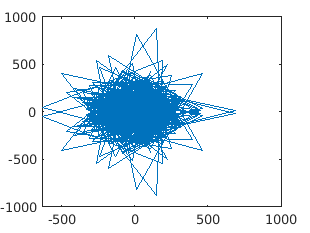

freqAxis = (0:length(mySpeech)-1)*44100/length(mySpeech);
plot(fft(mySpeech))

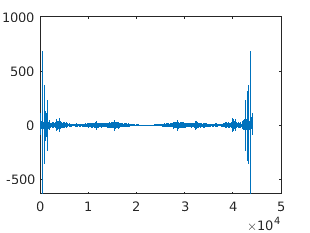

plot(freqAxis, real(fft(mySpeech)))

### Part D)

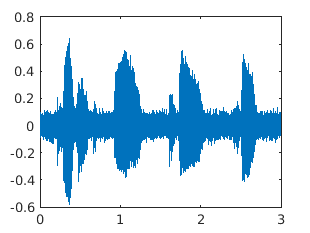

sampleNoise = awgn(mySpeech, 30);
noiseFFT = fft(sampleNoise);
timeAxis = (0:length(noiseFFT)-1)*3/length(noiseFFT);
freqAxis = (0:length(noiseFFT)-1)*44100/length(noiseFFT);

figure(2)
plot(timeAxis, sampleNoise)

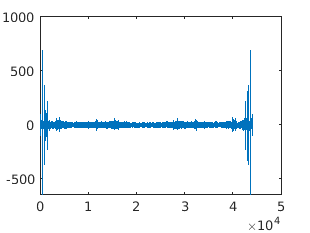

plot(freqAxis, real(noiseFFT))

sound(sampleNoise, 44100);

Fsf = 44100;
lpFilter = designfilt('lowpassfir','PassbandFrequency',0.1134, ...
    'StopbandFrequency', 0.907, 'PassbandRipple',1, ...
    'StopbandAttenuation',95)

lpFilter =  digitalFilter with properties:

           Coefficients: [0.0329 0.1630 0.3241 0.3241 0.1630 0.0329]

   Specifications:
      FrequencyResponse: 'lowpass'
        ImpulseResponse: 'fir'
             SampleRate: 2
         PassbandRipple: 1
    StopbandAttenuation: 95
      PassbandFrequency: 0.1134
      StopbandFrequency: 0.9070
           DesignMethod: 'equiripple'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


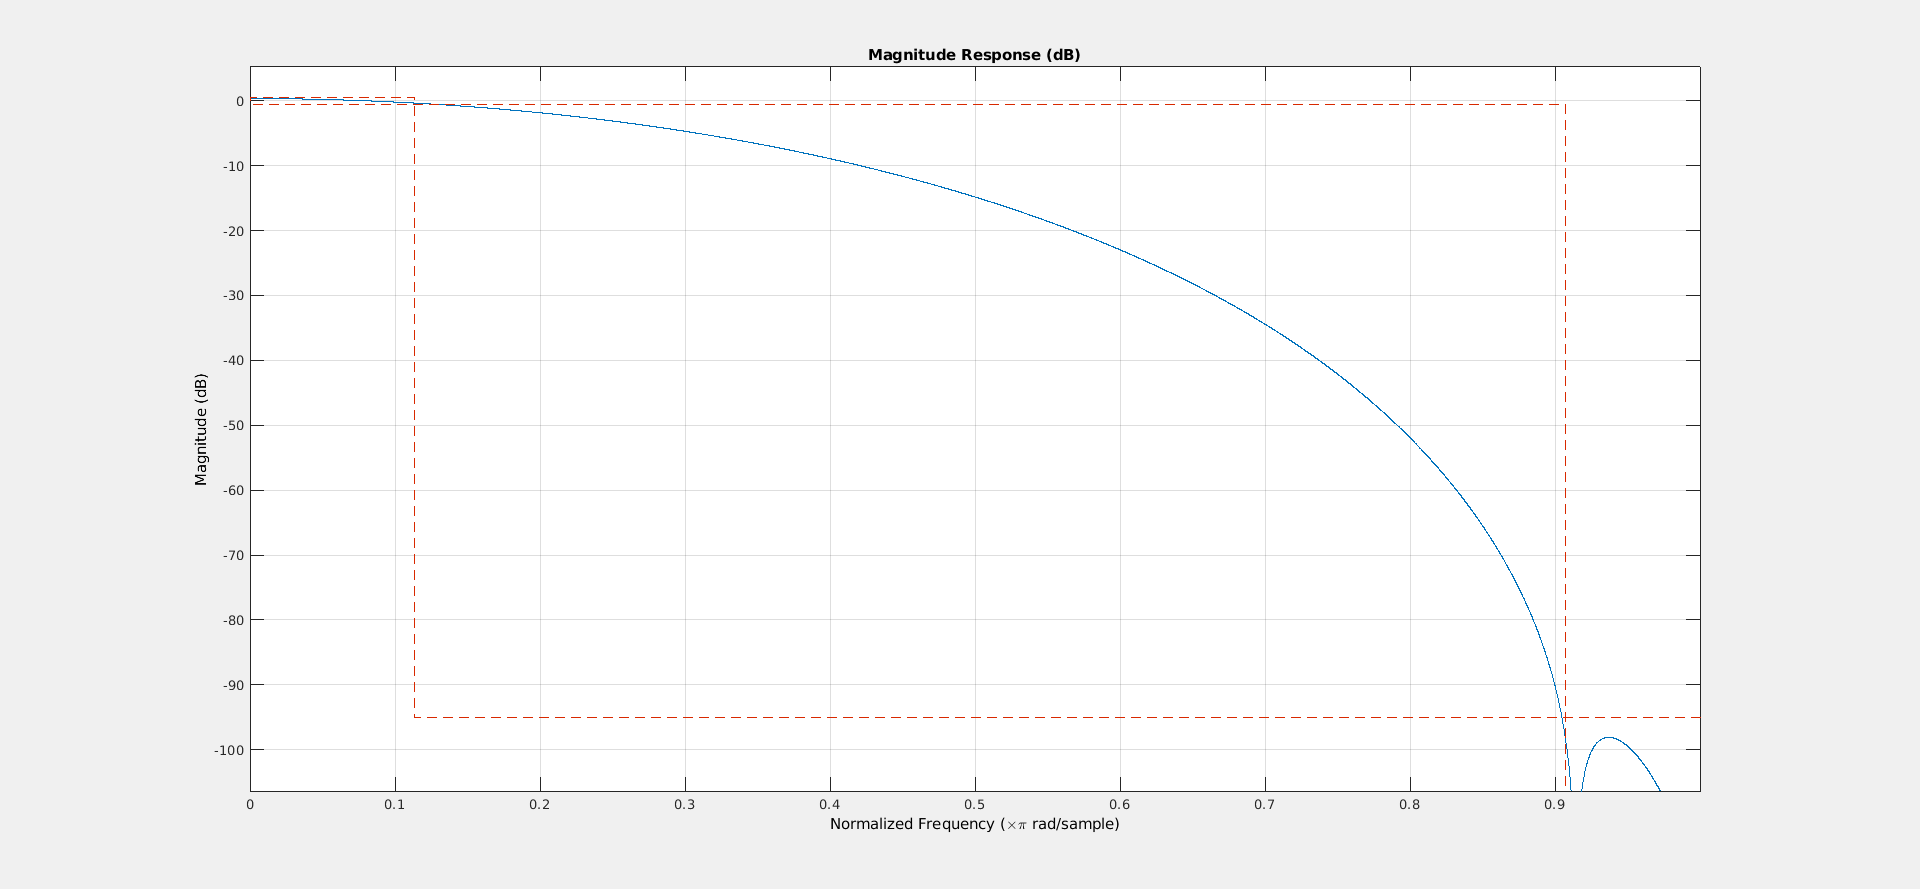

fvtool(lpFilter)

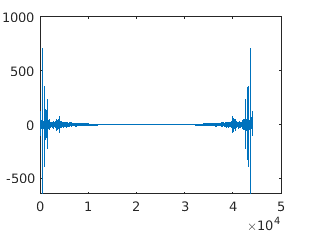

filteredSpeech = filter(lpFilter,sampleNoise);
plot(freqAxis,real(fft(filteredSpeech)));

sound(filteredSpeech, 44100);

### Part E)

#### Q3

cd /home/uki/Documents/MATLAB/IR/

[h, Fh1] = audioread('BiomedicalSciences.wav');
h1 = sum(h, 2) / size(h, 2);
[h, Fh2] = audioread('CarpenterCenter.wav');
h2 = sum(h, 2) / size(h, 2);
[h, Fh3] = audioread('GalbraithHall.wav');
h3 = sum(h, 2) / size(h, 2);

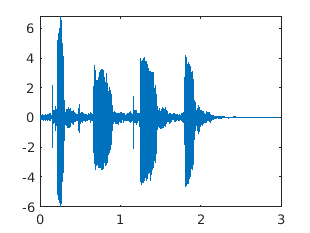

y1 = conv(h1, mySpeech);
timeAxis = (0:length(y1)-1)*3/length(y1);
plot(timeAxis, y1)

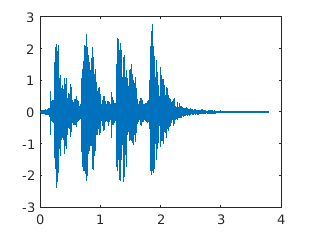

y2 = conv(h2, mySpeech);
timeAxis = (0:length(y2)-1)*3/length(y1);
plot(timeAxis, y2)

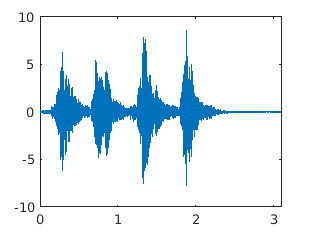

y3 = conv(h3, mySpeech);
timeAxis = (0:length(y3)-1)*3/length(y1);
plot(timeAxis, y3)

sound(y1);

sound(y2);

sound(y3);

#### Q4

H1 = real(fft(h1));
H2 = real(fft(h2));
H3 = real(fft(h3));
X = real(fft(mySpeech));
Y1 = H1.* X(1:length(H1));
Y2 = H2.* X(1:length(H2));
Y3 = H3.* X(1:length(H3));

sound(Y1);

sound(Y2);

sound(Y3);

#### Q6, 7

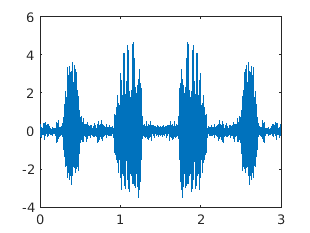

Error using plot
Vectors must be the same length.

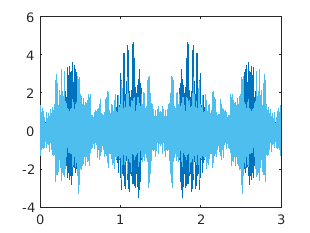

y1prime = real(ifft(Y1));
timeAxis = (0:length(y1prime)-1)*3/length(y1prime);
plot(timeAxis, y1prime);

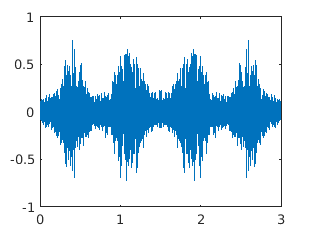

y2prime = real(ifft(Y2));
timeAxis = (0:length(y2prime)-1)*3/length(y2prime);
plot(timeAxis, y2prime);

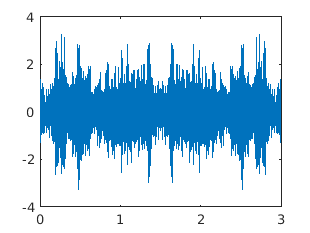

y3prime = real(ifft(Y3));
timeAxis = (0:length(y3prime)-1)*3/length(y3prime);
plot(timeAxis, y3prime);